# Funciones de trasferencia

%clear, clc

g = 9.81; % gravedad
m = 1.6; % masa del dron
[I_xx, I_yy, I_zz] = deal(0.021915027, 0.022124548, 0.042349865);
kf = 0.7*9.81; % coeficiente de empuje
km = 0.2; % coeficiente de arrastre
l = 0.268554; % largo de los brazos
om_0 = sqrt(m*g/(4*kf)); % velocidad de motores con dron flotando
om_1 = sqrt(m*g/(4*km)); % velocidad de motores dron rumbo fijo
mk = log(1-0.9933)/-0.1; % retraso motores

## Controlador x

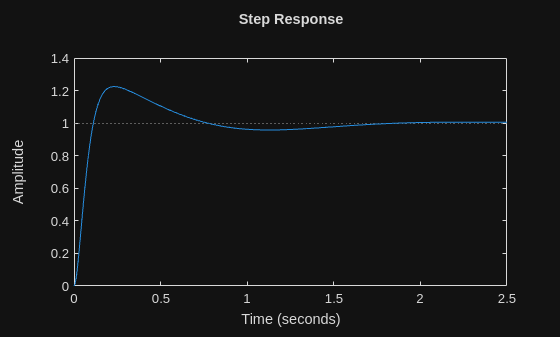

% bucle orientacion
g_the = tf(2*mk*om_0,[I_yy I_yy*mk 0 0]);
c_the = tf([0.22692 0.7758 1.9892],[1 0]); % D P I
step(feedback(series(c_the,g_the),1))

% bucle posicion
g_x = tf(2*mk*om_0*g,[I_yy I_yy*mk 0 0 0 0]);
g_xthe = (g_x*c_the)/(1+g_the*c_the);
g_xthe.Numerator

ans = 1×1 cell array
    {[0 0 0 0 3.7272 199.3153 670.5324 1.6355e+03 0 0 0]}


g_xthe.Denominator

ans = 1×1 cell array
    {[4.8950e-04 0.0490 1.6064 20.3176 68.3519 166.7187 0 0 0 0 0]}


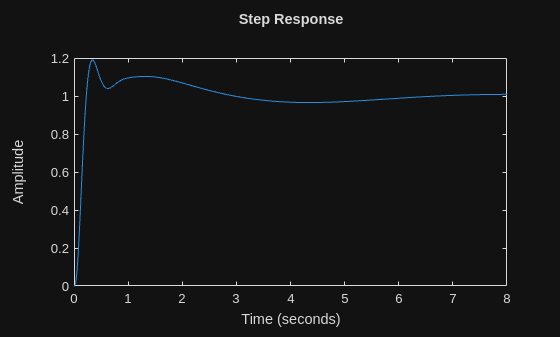

P = 0.6*0.8606;
I = 0.6*0.8606/(0.5*2.077);
D = 0.6*0.8606*2.077/8;
c_xthe = tf([D*5 P I],[1 0]);
step(feedback(series(c_xthe,g_xthe),1))

## Controlador y

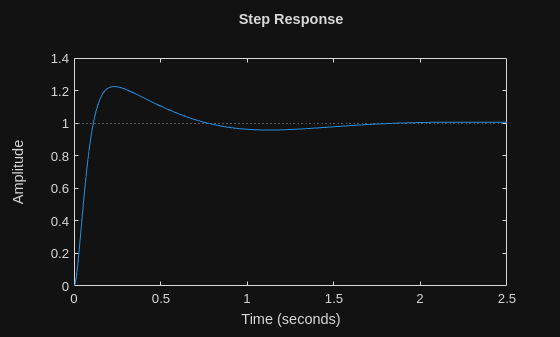

% bucle orientacion
g_phi = tf(2*mk*om_0,[I_xx I_xx*mk 0 0]);
c_phi = tf([0.22482 0.7686 1.9708],[1 0]); % D P I
step(feedback(series(c_phi,g_phi),1))

% bucle posicion
g_y = tf(-2*mk*om_0*g,[I_xx I_xx*mk 0 0 0 0]);
g_yphi = (g_y*c_phi)/(1+g_phi*c_phi);
g_yphi.Numerator

ans = 1×1 cell array
    {[0 0 0 0 -3.6578 -195.6004 -658.0193 -1.6050e+03 0 0 0]}


g_yphi.Denominator

ans = 1×1 cell array
    {[4.8027e-04 0.0481 1.5762 19.9389 67.0764 163.6124 0 0 0 0 0]}


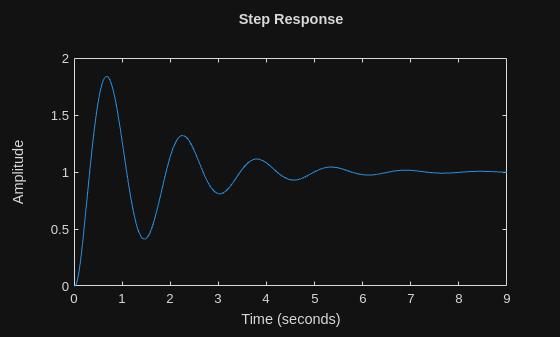

P = 0.6*2.097;
I = 0.6*2.097/(0.5*1.451);
D = 0.6*2.097*1.451/8;
c_yphi = tf([D P I],[1 0]);
step(feedback(series(-c_yphi,g_yphi),1))